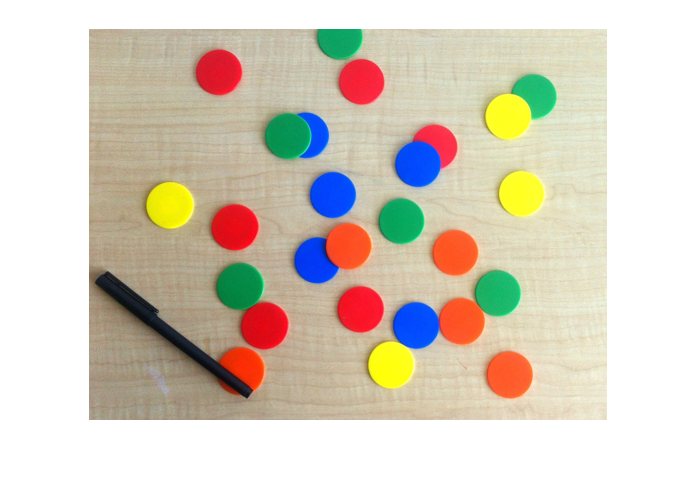

img = imread("coloredchips.png");
imshow(img)

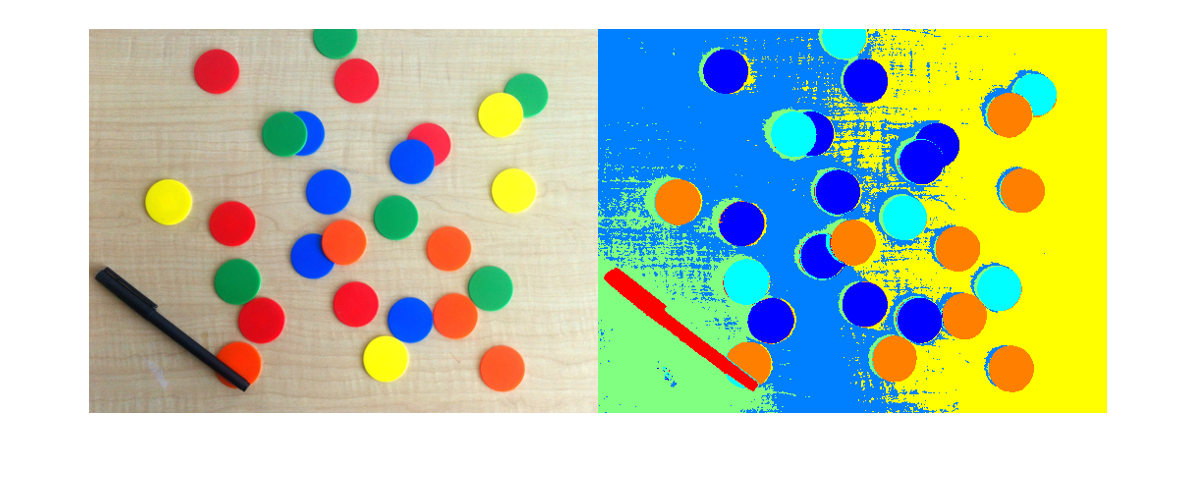


HSV = rgb2hsv(img);
K = 7;

labels = imsegkmeans(im2single(HSV),K);

montage({img,label2rgb(labels)})

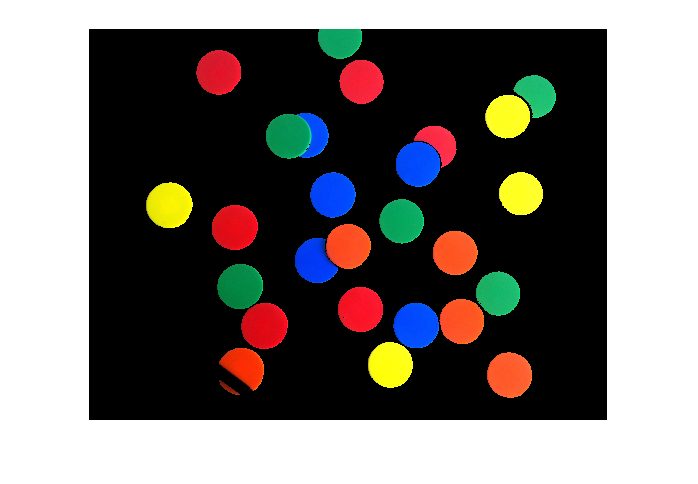

chipmask = HSV(:,:,2) > 0.75;

HSVchip = HSV;

HSVchip(~repmat(chipmask,1,1,3)) = 0;

imshow(hsv2rgb(HSVchip));

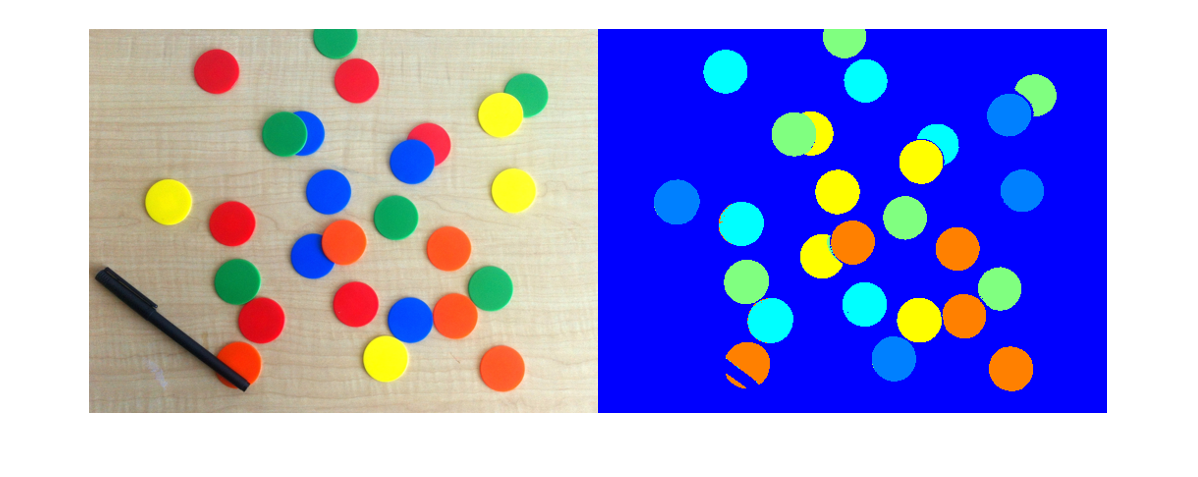

K = 6;

labels = imsegkmeans(im2single(HSVchip),K);

montage({img,label2rgb(labels)})